# Общая геометрия эксперимента

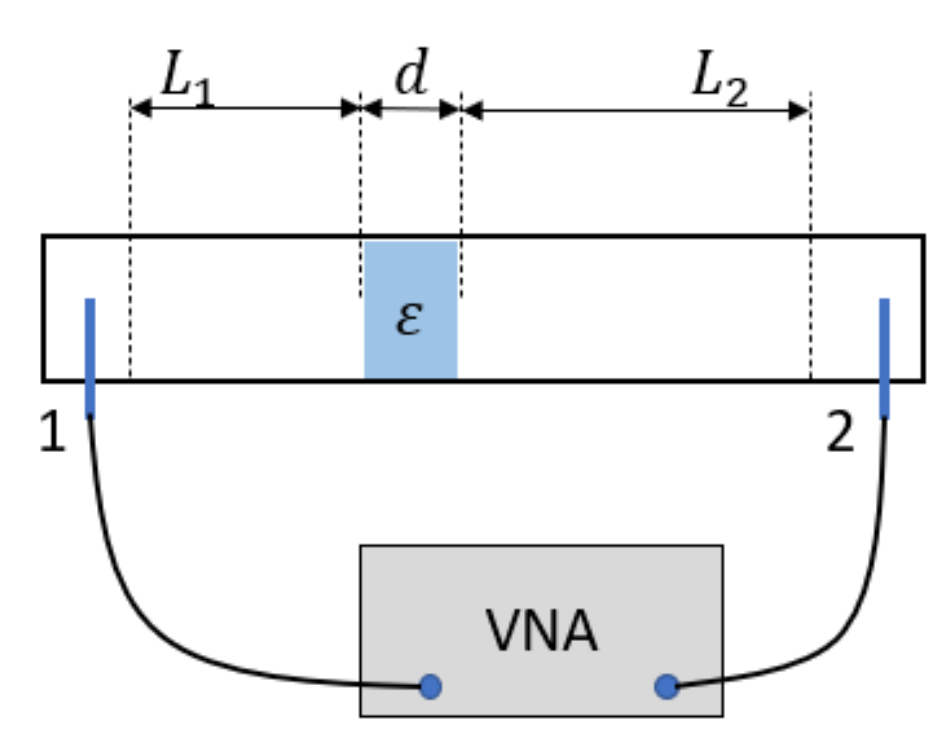

clear;

f=8*10^(9);
c=2.99*10^(8);
lambda0=c/f/sqrt(2.89)*1000

lambda0 = 21.9853

disp(2*lambda0);

   43.9706



disp(3*lambda0);

   65.9559



[eps1,freq1]=read_data_phase_corr('15.s2p',10.62*10^(-3),0);
[eps2,freq2]=read_data_phase_corr('30.s2p',30.13*10^(-3),1);
[eps3,freq3]=read_data_phase_corr('50.s2p',50.2*10^(-3),2);
[eps4,freq4]=read_data_phase_corr('70.s2p',70.15*10^(-3),3);

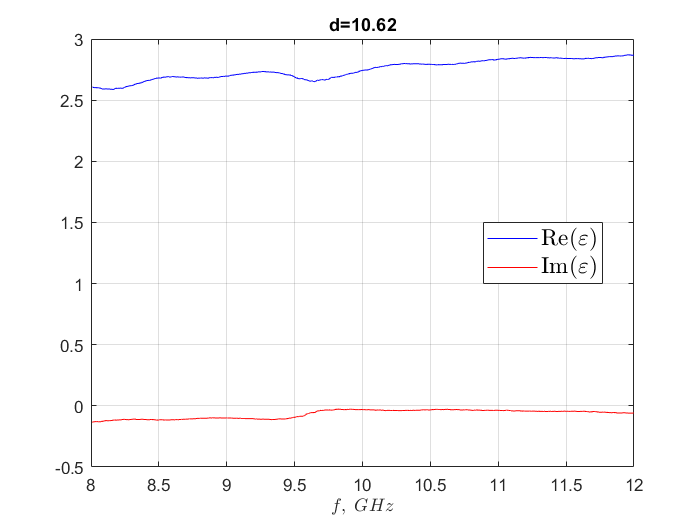

close all;

plot(freq1*10^(-9),real(eps1),'-b','DisplayName','$\mathrm{Re}(\varepsilon)$');
hold on;
grid on;
plot(freq1*10^(-9),imag(eps1),'-r','DisplayName','$\mathrm{Im}(\varepsilon)$');
title('d=10.62')
xlabel('$f,\;GHz$','Interpreter',"latex");
legend('Interpreter',"latex",'Location','best','FontSize',14);

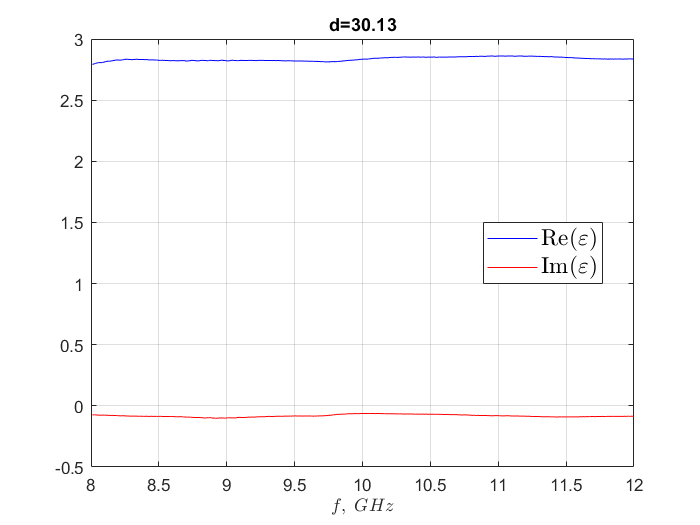

close all;

plot(freq2*10^(-9),real(eps2),'-b','DisplayName','$\mathrm{Re}(\varepsilon)$');
hold on;
grid on;
plot(freq2*10^(-9),imag(eps2),'-r','DisplayName','$\mathrm{Im}(\varepsilon)$');
title('d=30.13')
xlabel('$f,\;GHz$','Interpreter',"latex");
legend('Interpreter',"latex",'Location','best','FontSize',14);

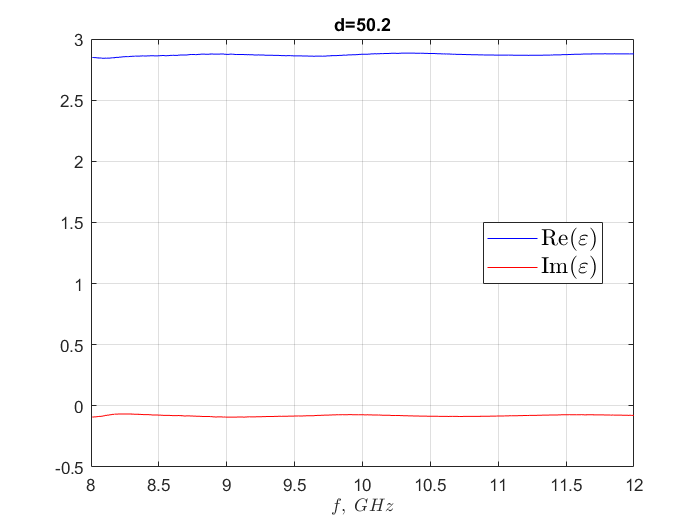

close all;

plot(freq3*10^(-9),real(eps3),'-b','DisplayName','$\mathrm{Re}(\varepsilon)$');
hold on;
grid on;
plot(freq3*10^(-9),imag(eps3),'-r','DisplayName','$\mathrm{Im}(\varepsilon)$');
title('d=50.2')
xlabel('$f,\;GHz$','Interpreter',"latex");
legend('Interpreter',"latex",'Location','best','FontSize',14);

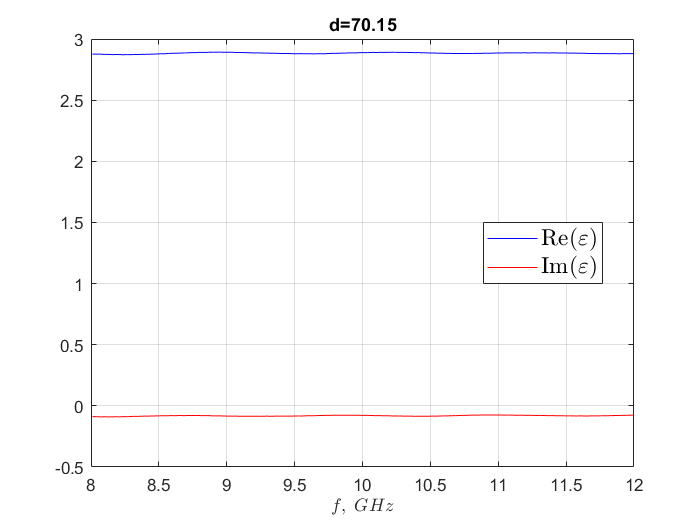

close all;

plot(freq4*10^(-9),real(eps4),'-b','DisplayName','$\mathrm{Re}(\varepsilon)$');
hold on;
grid on;
plot(freq4*10^(-9),imag(eps4),'-r','DisplayName','$\mathrm{Im}(\varepsilon)$');
title('d=70.15')
xlabel('$f,\;GHz$','Interpreter',"latex");
legend('Interpreter',"latex",'Location','best','FontSize',14);

# Общий график

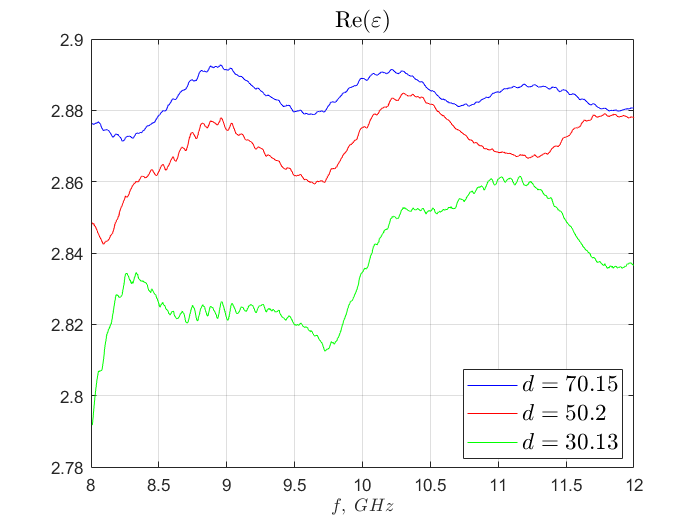

close all;


plot(freq4*10^(-9),real(eps4),'-b','DisplayName','$d=70.15$');
hold on;
grid on;
plot(freq3*10^(-9),real(eps3),'-r','DisplayName','$d=50.2$');
hold on;
plot(freq2*10^(-9),real(eps2),'-g','DisplayName','$d=30.13$');

title('$\mathrm{Re} (\varepsilon)$',"Interpreter","latex",'FontSize',14);


xlabel('$f,\;GHz$','Interpreter',"latex");
legend('Interpreter',"latex",'Location','best','FontSize',14);

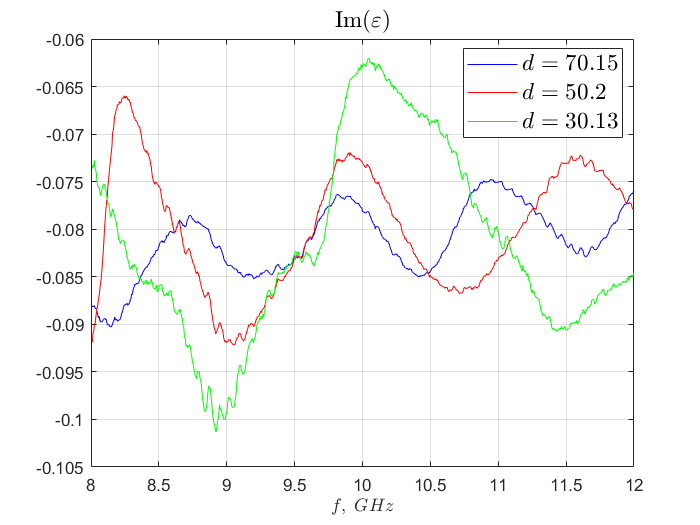

close all;


plot(freq4*10^(-9),imag(eps4),'-b','DisplayName','$d=70.15$');
hold on;
grid on;
plot(freq3*10^(-9),imag(eps3),'-r','DisplayName','$d=50.2$');
hold on;
plot(freq2*10^(-9),imag(eps2),'-g','DisplayName','$d=30.13$');

title('$\mathrm{Im} (\varepsilon)$',"Interpreter","latex",'FontSize',14);


xlabel('$f,\;GHz$','Interpreter',"latex");
legend('Interpreter',"latex",'Location','best','FontSize',14);

# S - параметры пустого волновода

[ee,ff,S11,S21]=read_data_phase_corr('00.s2p',10.62*10^(-3),0);

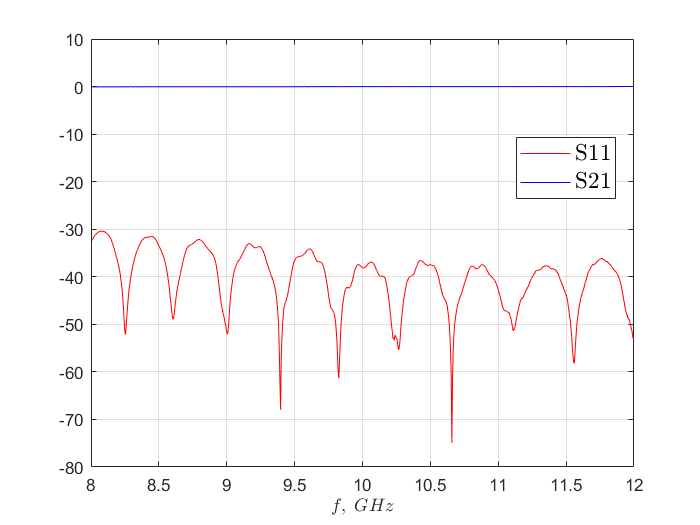

close all;

plot(ff*10^(-9),20*log10(abs(S11)),'-r','DisplayName','S11');
hold on;
grid on;
plot(ff*10^(-9),20*log10(abs(S21)),'-b','DisplayName','S21');
xlabel('$f,\;GHz$','Interpreter',"latex");
legend('Interpreter',"latex",'Location','best','FontSize',14);

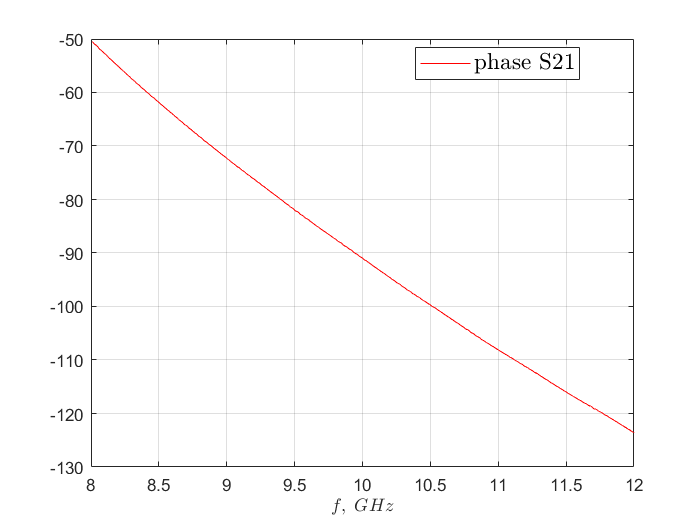

close all;

plot(ff*10^(-9),angle(S21)*180/pi,'-r','DisplayName','phase S21');
grid on;
xlabel('$f,\;GHz$','Interpreter',"latex");
legend('Interpreter',"latex",'Location','best','FontSize',14);

# S - параметры с образцом

[ff,S11,S12,S21,S22]=get_s('70.s2p');

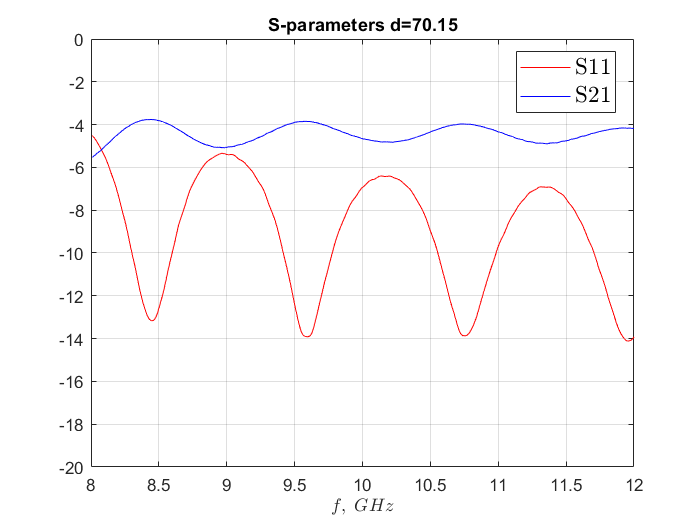

close all;

plot(ff*10^(-9),20*log10(abs(S11)),'-r','DisplayName','S11');
hold on;
grid on;
plot(ff*10^(-9),20*log10(abs(S21)),'-b','DisplayName','S21');
xlabel('$f,\;GHz$','Interpreter',"latex");
legend('Interpreter',"latex",'Location','best','FontSize',14);
ylim([-20,0]);
title('S-parameters d=70.15')

function [eps,freq,S11,S21] = read_data(filename,d,num_2pi)
    if nargin<3
        num_2pi=0;
    end
    
    c=2.998*10^8;
    a = 23.1*10^(-3); % размер большей стенки волновода
    f0=c/(2*a);
    L=270*10^(-3);
    
    L2=130*10^(-3);
    L1=L-d-L2;
    
    data=read(rfdata.data,filename);
    freq=data.Freq;
    S_mat=data.S_Parameters;
    S11=reshape(S_mat(1,1,:),[],1);
    S21=reshape(S_mat(2,1,:),[],1);
    
    %de-emdedding
    exp1=exp((1j*2*pi*L1/c.*freq).*sqrt(1-f0^2./freq.^2));
    exp2=exp((1j*2*pi*L2/c.*freq).*sqrt(1-f0^2./freq.^2));
    %exp0=exp(-(1j*2*pi*L/c.*freq).*sqrt(1-f0^2./freq.^2));
    
    S21=S21.*exp1.*exp2;    %.*exp0;
    S11=S11.*exp1.*exp1;   %.*exp0.*exp0;
    
    
    X=(S11.^2-S21.^2+1)./(2*S11);
    G=zeros(size(X));
    
    for i=1:size(X)
        a=X(i);
        b=sqrt(a^2-1);
        if abs(a+b)<=1
            G(i)=a+b;
        else
            G(i)=a-b;
        end
    end
    
    exp_gammad=(1-(S11+S21).*G)./(S11+S21-G);
    gammad=log(abs(exp_gammad))+1j*angle(exp_gammad)-1j*2*pi*num_2pi;
    
    eps=-(c./(2*pi*d.*freq).*gammad).^2+f0^2./(freq.^2);
end

% gammad=zeros(size(freq));
% exp_0=1;
% sum_angle=0;
% 
% for i=1:size(freq)
%     sum_angle=sum_angle+angle(exp_gammad(i)/exp_0);
%     gammad(i)=log(abs(exp_gammad(i)))  +  1j*sum_angle+1j*2*pi*num_2pi;
%     exp_0=exp_gammad(i);
% end

%Правильная функция с поправками по статье Третьякова (2011), практически
%во всех случаях данные считываются корректно.

function [eps,freq,S11,S21] = read_data_phase_corr(filename,d,num_2pi)
    if nargin<3
        num_2pi=0;
    end
    
    c=2.998*10^8;
    a = 23.1*10^(-3); % размер большей стенки волновода
    f0=c/(2*a);
    L=270*10^(-3);
    
    L2=130*10^(-3);
    L1=L-d-L2;
    
    
    data=read(rfdata.data,filename);
    freq=data.Freq;
    S_mat=data.S_Parameters;
    S11=reshape(S_mat(1,1,:),[],1);
    S21=reshape(S_mat(2,1,:),[],1);
    
    %de-emdedding
    exp1=exp((1j*2*pi*L1/c.*freq).*sqrt(1-f0^2./freq.^2));
    exp2=exp((1j*2*pi*L2/c.*freq).*sqrt(1-f0^2./freq.^2));
    
    S21=S21.*exp1.*exp2;
    S11=S11.*exp1.*exp1;
    
    
    X=(S11.^2-S21.^2+1)./(2*S11);
    G=zeros(size(X));
    
    for i=1:size(X)
        a=X(i);
        b=sqrt(a^2-1);
        if abs(a+b)<=1
            G(i)=a+b;
        else
            G(i)=a-b;
        end
    end
    
    exp_gammad=(1-(S11+S21).*G)./(S11+S21-G);
    gammad=zeros(size(freq));
    exp_0=1;
    sum_angle=0;
    
    for i=1:size(freq)
        sum_angle=sum_angle+angle(exp_gammad(i)/exp_0);
        gammad(i)=log(abs(exp_gammad(i)))  +  1j*sum_angle+1j*2*pi*num_2pi;
        exp_0=exp_gammad(i);
    end

    
    eps=-(c./(2*pi*d.*freq).*gammad).^2+f0^2./(freq.^2);
end





function [freq,S11,S12,S21,S22] = get_s(filename)
    data=read(rfdata.data,filename);
    freq=data.Freq;
    S_mat=data.S_Parameters;
    S11=reshape(S_mat(1,1,:),[],1);
    S21=reshape(S_mat(2,1,:),[],1);
    S12=reshape(S_mat(1,2,:),[],1);
    S22=reshape(S_mat(2,2,:),[],1);
end
